# E7-bis: Segmentació

#### Segmentació assistida

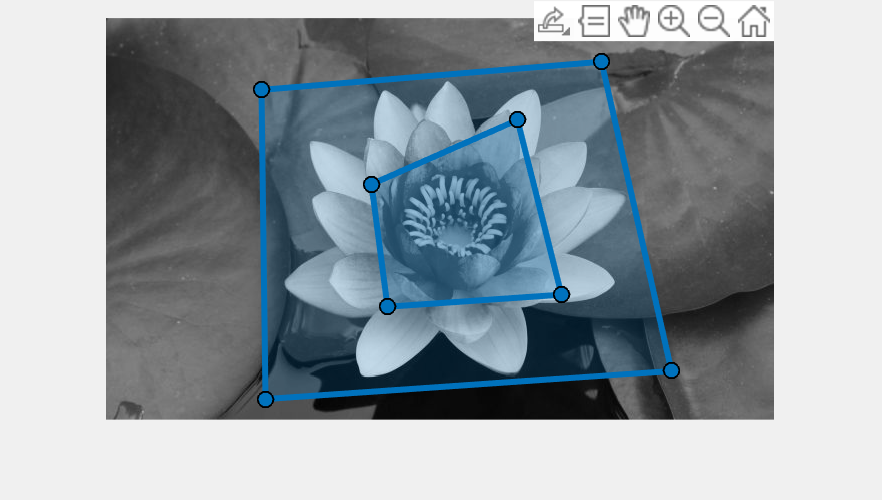

I = rgb2gray(imread("nenufar.jpg"));
imshow(I);
[f, c] = size(I);
roiPoints = drawpolygon;
BK = not(poly2mask(roiPoints.Position(:,1), roiPoints.Position(:,2), f, c));
roiPoints = drawpolygon;

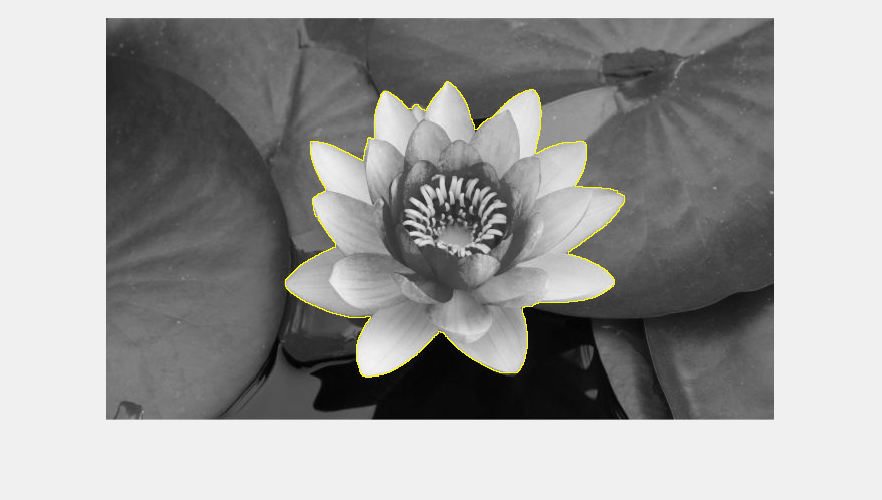

FG = poly2mask(roiPoints.Position(:,1), roiPoints.Position(:,2), f, c);

MASK = BK|FG;

% imatge gradient 
Grad = uint8(imgradient(I));
G = imimposemin(Grad,MASK);

WS = watershed(G);
imshow(imoverlay(I,(WS == 0)),[]);

#### Segmentació assistida utilitzant graph min cut

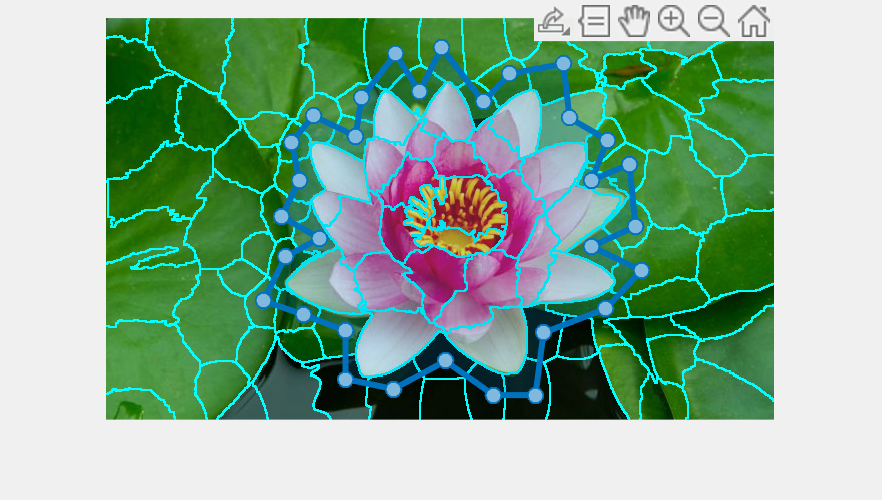

I = imread("nenufar.jpg");
[SP, N] = superpixels(I, 100);
BW = boundarymask(SP);
imshow(imoverlay(I,BW,'cyan'));

[f, c] = size(SP);
roiPoints = drawpolygon;

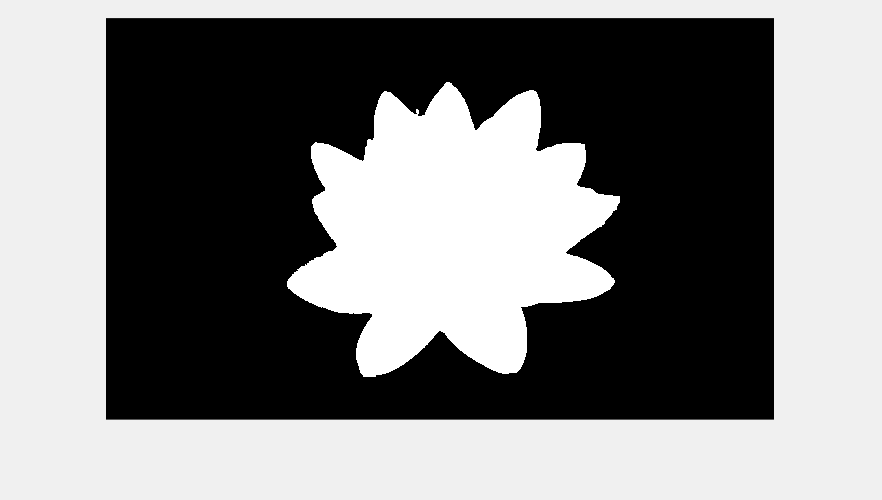

roi = poly2mask(roiPoints.Position(:,1), roiPoints.Position(:,2), f, c);
BW = grabcut(I,SP,roi); % SP -> etiquetes, roi -> regió d'interès
imshow(BW)

#### Segmentació per color

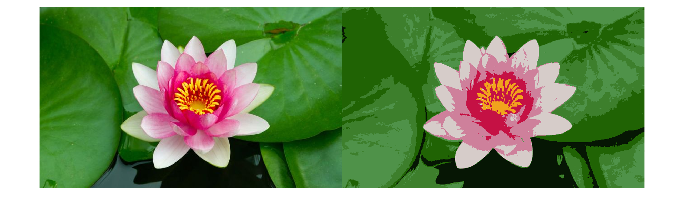

% reduim la quantitat de colors RGB
I = imread('nenufar.jpg');
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

% preparem les dades per kmeans
O = double([R(:) G(:) B(:)] );

% etiquetes i centroides obtinguts per kmeans
k = 8;
[C, CEN] = kmeans(O,k,'MaxIter',200);

% ara per visualitzar el resultat substituir cada pixel per el seu color representant
[f, c, p] = size(I);
RGB2 = uint8(zeros(f,c,p));
C = reshape(C,[f c]);
for i = 1: f
    for j = 1: c
        RGB2(i,j,1) = uint8(CEN(C(i,j),1));
        RGB2(i,j,2) = uint8(CEN(C(i,j),2));
        RGB2(i,j,3) = uint8(CEN(C(i,j),3));
    end
end

% mostrem en RGB els resultats
montage({I,RGB2});

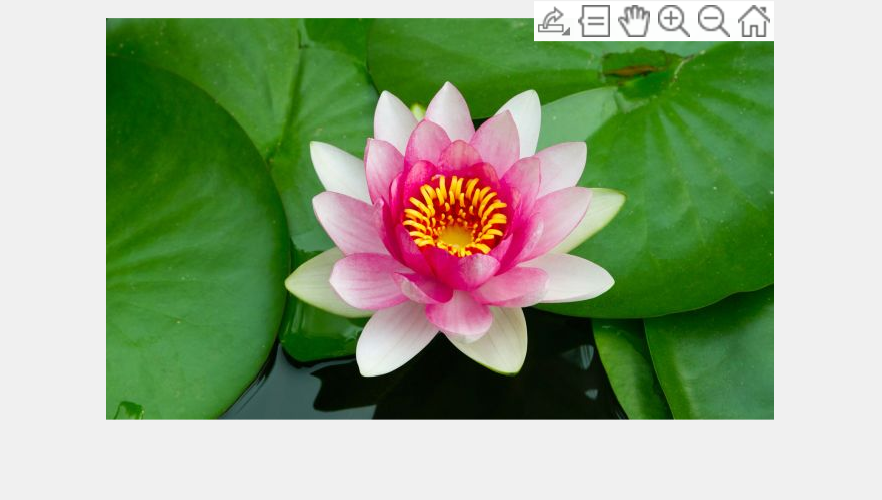

%segmentacio en base a una area (rectangle) escollida per l'usuari
imshow(I);
rect = getrect;

[f, c, p] = size(I);

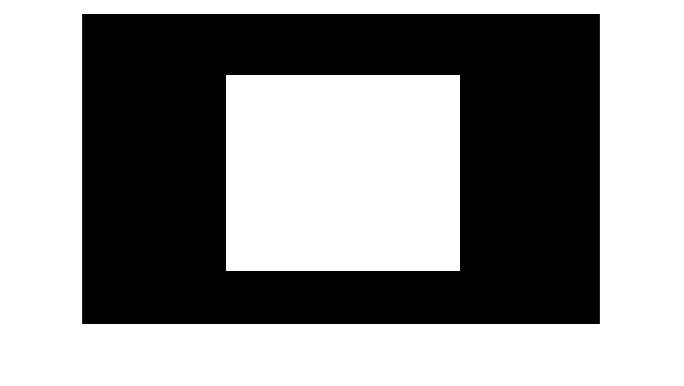

% mascara de la seleccio rect
MASK = false([f, c]);
MASK(rect(2):rect(2)+rect(4),rect(1):rect(1)+rect(3)) = 1;
imshow(MASK);

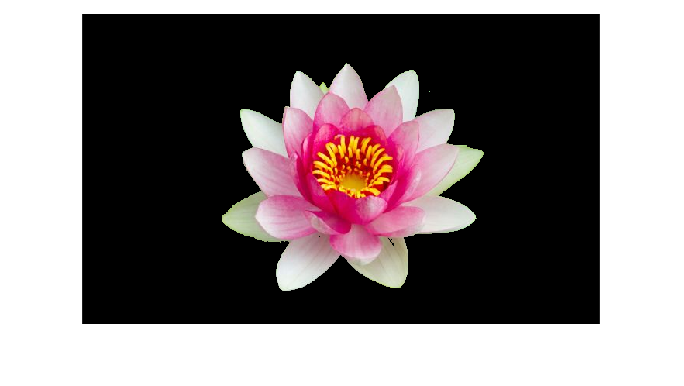


% comptem quants colors cauen dins i quants fora del rectangle
Hist = zeros(k,2);
for i = 1: f*c
    if MASK(i)
        Hist(C(i),2) = Hist(C(i),2)+1; % cau dins
    else
        Hist(C(i),1) = Hist(C(i),1)+1;% cau fora
    end
end

% classifiquem els colors com de l'objecte o no
% segons si en hi han mes fora que dintre del rect
CLS = Hist(:,1) < Hist(:,2);
% classifiquem cada pixel segons el color
M = false([f, c]);
for i= 1: f*c
   M(i) = CLS(C(i));
end
imshow(uint8(M).*I);